## Data Conversion

- String to cell` cellstr()`

- Table to cell  `table2cell()`

- Timetable to cell 

- Struct to cell

c = ["Abisoye" "Akinloye" "Samson"]

c = 1×3 string array
    "Abisoye"    "Akinloye"    "Samson"


whos c

  Name      Size            Bytes  Class     Attributes

  c         1x3               274  string              



C = cellstr(c)

C = 1×3 cell array
    {'Abisoye'}    {'Akinloye'}    {'Samson'}


whos C

  Name      Size            Bytes  Class    Attributes

  C         1x3               354  cell               



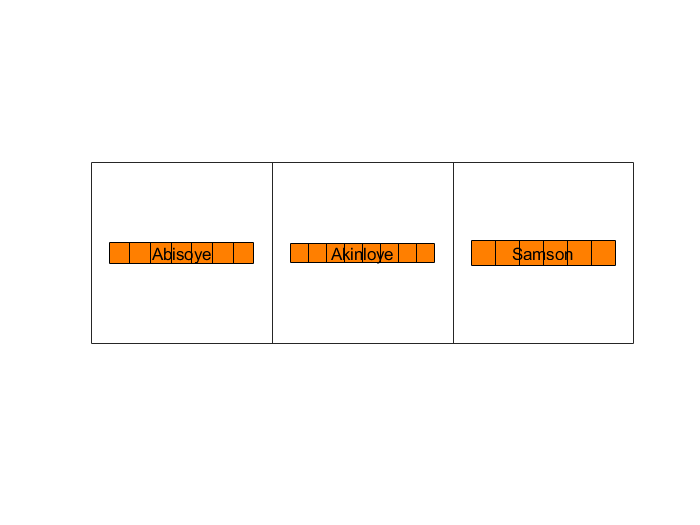

cellplot(C)

**N.B: **For array of character, it must have the same size.

charst = ['abc'; 'bcd'; 'cde']

charst = 3×3 char array
    'abc'
    'bcd'
    'cde'


whos charst

  Name        Size            Bytes  Class    Attributes

  charst      3x3                18  char               



**TABLE TO CELL**

Age = [15 28 23 19 22];
Gender = ["M", "M", "F", "M", "F"];
Bloodpressure = [124 109 125 117 122];

T = table(Gender', Age', Bloodpressure')

T = 5×3 table
    Var1    Var2    Var3
    ____    ____    ____

    "M"      15     124 
    "M"      28     109 
    "F"      23     125 
    "M"      19     117 
    "F"      22     122 


T.Properties.VariableNames = {'Gender', 'Age', 'Bloodpressure'}

T = 5×3 table
    Gender    Age    Bloodpressure
    ______    ___    _____________

     "M"      15          124     
     "M"      28          109     
     "F"      23          125     
     "M"      19          117     
     "F"      22          122     


T.Properties.RowNames = {'Stephen', 'Emmanuel', 'Christy', 'Paul', 'Faith'}

T = 5×3 table
                Gender    Age    Bloodpressure
                ______    ___    _____________

    Stephen      "M"      15          124     
    Emmanuel     "M"      28          109     
    Christy      "F"      23          125     
    Paul         "M"      19          117     
    Faith        "F"      22          122     


sortrows(T, 'RowNames')

ans = 5×3 table
                Gender    Age    Bloodpressure
                ______    ___    _____________

    Christy      "F"      23          125     
    Emmanuel     "M"      28          109     
    Faith        "F"      22          122     
    Paul         "M"      19          117     
    Stephen      "M"      15          124     


T1 = table2cell(T)

T1 = 5×3 cell array
    {["M"]}    {[15]}    {[124]}
    {["M"]}    {[28]}    {[109]}
    {["F"]}    {[23]}    {[125]}
    {["M"]}    {[19]}    {[117]}
    {["F"]}    {[22]}    {[122]}


% add the varible name

T1 = [T.Properties.VariableNames; T1]

T1 = 6×3 cell array
    {'Gender'}    {'Age'}    {'Bloodpressure'}
    {["M"   ]}    {[ 15]}    {[          124]}
    {["M"   ]}    {[ 28]}    {[          109]}
    {["F"   ]}    {[ 23]}    {[          125]}
    {["M"   ]}    {[ 19]}    {[          117]}
    {["F"   ]}    {[ 22]}    {[          122]}


**TIMETABLE TO A CELL**

- Convert timetable to table `timetable2table()`

- Then, convert table to cell `table2cell()`

Temp = [37.3; 39.1; 42.4];
Humidity = [29.4; 29.6; 30];
Precip = [0.1; 0.9; 0];

today = datetime('today');
yesterday = datetime('yesterday');
tomorrow = datetime('tomorrow');

date = [yesterday;today;tomorrow];

TT = timetable(date,Temp,Humidity,Precip)

TT = 3×3 timetable
       date        Temp    Humidity    Precip
    ___________    ____    ________    ______

    11-Jan-2023    37.3      29.4       0.1  
    12-Jan-2023    39.1      29.6       0.9  
    13-Jan-2023    42.4        30         0  


% timetable to table
CT = timetable2table(TT)

CT = 3×4 table
       date        Temp    Humidity    Precip
    ___________    ____    ________    ______

    11-Jan-2023    37.3      29.4       0.1  
    12-Jan-2023    39.1      29.6       0.9  
    13-Jan-2023    42.4        30         0  


% don't convert the row time

RT = timetable2table(TT,"ConvertRowTimes",false)

RT = 3×3 table
    Temp    Humidity    Precip
    ____    ________    ______

    37.3      29.4       0.1  
    39.1      29.6       0.9  
    42.4        30         0  


T_cell = table2cell(RT)

T_cell = 3×3 cell array
    {[37.3000]}    {[29.4000]}    {[0.1000]}
    {[39.1000]}    {[29.6000]}    {[0.9000]}
    {[42.4000]}    {[     30]}    {[     0]}


T_cell = [RT.Properties.VariableNames; T_cell]

T_cell = 4×3 cell array
    {'Temp'   }    {'Humidity'}    {'Precip'}
    {[37.3000]}    {[ 29.4000]}    {[0.1000]}
    {[39.1000]}    {[ 29.6000]}    {[0.9000]}
    {[42.4000]}    {[      30]}    {[     0]}


**STRUCT TO CELL**

student = struct('Name','','Age',{},'Matric_no',{})


student = 

  0×0 empty struct array with fields:

    Name
    Age
    Matric_no



student(1).Name = 'Abisoye Akinloye';
student(1).Age = 23;
student(1).Matric_no = 160173;

student

student = struct with fields:
         Name: 'Abisoye Akinloye'
          Age: 23
    Matric_no: 160173


Struct_cell = struct2cell(student)

Struct_cell = 3×1 cell array
    {'Abisoye Akinloye'}
    {[              23]}
    {[          160173]}


**MAP CONTAINER TO CELL**